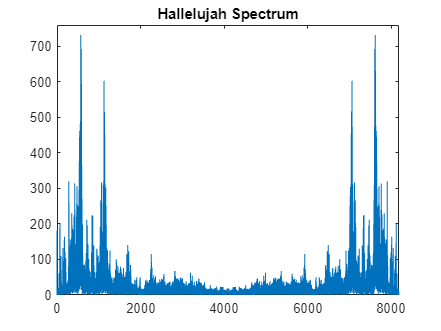

% 
load handel.mat  
x = y'; 
x = x(1:65536);

% Calculate FFT and freq axis 
Y = fft(y); 
freqInc = Fs / length(Y); 
freqAxis = 0:freqInc:(Fs - freqInc); 

% Plot spectrum
plot(freqAxis, abs(Y)) 
title("Hallelujah Spectrum")
axis([0 8191 0 760])

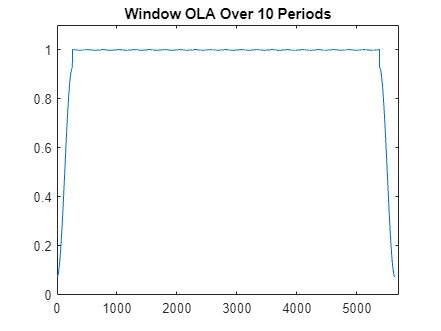


% Attempt deconstruction and reconstruction
% by windowed FFT 

% Process variables
winSize = 512; 
ovrlapSF = 2; 
outp = zeros(1, length(x));

% Plot window with chosen overlap to check COLA 
w = hamming(winSize)'; 
checkCOLA(w, length(w))

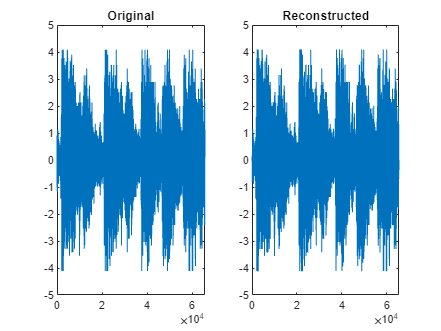


% Loop over samples and update window, 
% apply STFT to window, apply IFFT to window, 
% overlap add to output array 
for i = 0 : (length(x) / winSize) * 2 - 2
    % Calculate boundaries of current window
    St = i * winSize/2 + 1;         % Current window start pos
    Mid = (i + 1) * winSize/2;      % Current window mid pos 
    End = Mid + winSize/2;            % Curr window end pos
    % Update current window from samples
    samples = x(St : End);
    samples = samples .* w; 
    % Compute spectrum 
    S = fft(samples); 
    % ** Spectral Analysis ** 
    % Return to time domain
    samples = ifft(S);
    % Overlap add reconstruct
    outp(1, St : Mid) = outp(1, St : Mid) + samples(1 : winSize/2); % Overlap add
    outp(1, (Mid+1) : End) = samples(winSize/2+1:end);            % Append
end 

% Compare input sample with output sample reconstruction
subplot(1, 2, 1)
plot(normalize(x)) 
title('Original')
subplot(1, 2, 2)
plot(normalize(outp)) 
title('Reconstructed')